# Cviceni 8

## Redundance - kodovani

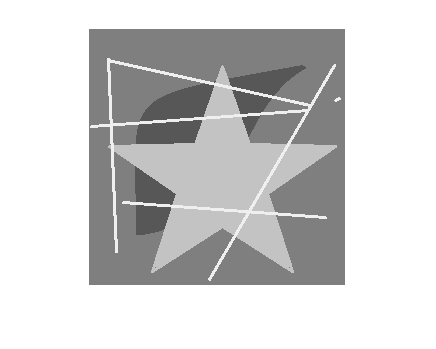

I1 = rgb2gray(imread('red1.png'));
figure, imshow(I1);

[M,N] = size(I1);

### Pocet barev v obraze

unique(I1)

ans = 4×1 uint8 column vector
    87
   127
   195
   239


### Pravdepodobnost kazde barvy

n = imhist(I1);
p = n/(M*N);
p(unique(I1)+1)

ans =     0.1031
    0.6026
    0.2455
    0.0488


## Kodovani

### pocet bitu pouzitych k zakodovani

l1 = 8*ones(256,1);

l1_avg = sum(l1.*p);
display(l1_avg);

l1_avg = 8

### Kodovani barev nestejne dlouhym kodem - pocet bitu

- 87 : 000 

- 127 : 1 

- 195 : 01 

- 239 : 001

l2 = zeros(256,1);
l2(88)=3;
l2(128) = 1;
l2(196) = 2;
l2(240) = 3;

l2_avg = sum(l2.*p);
display(l2_avg);

l2_avg = 1.5493

## Komprese a relativni redundance

b1 = M*N*l1_avg;
b2 = M*N*l2_avg;

% komprese
C = b1/b2;
display(C);

C = 5.1637


% relativni redundance
R = 1-(1/C);
display(R);

R = 0.8063

## UKOL 1

Spocitejte kompresi a relativni redundanci pokud pro obrazek red1.png (I1) vezmeme, ze kazda barva je kodovana 2 bity.

## Prostorova redundance

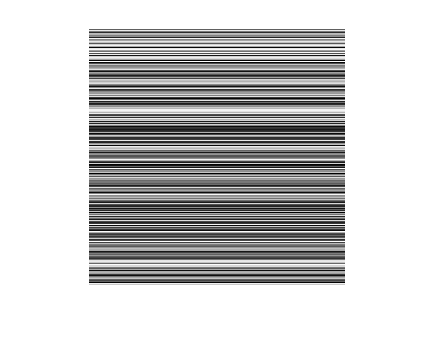

I2 = imread('red2.png');
figure, imshow(I2);

[M,N] = size(I2);

### Histogram

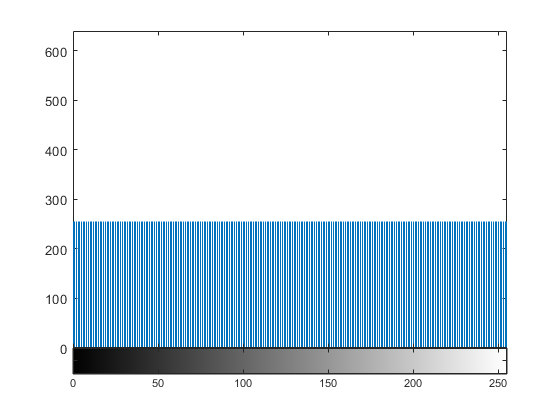

figure, imhist(I2);

### Pravdepodobnost kazde barvy

n = imhist(I2);
p = n/(M*N)

p =     0.0039
    0.0039
    0.0039
    0.0039
    0.0039
    0.0039
    0.0039
    0.0039
    0.0039
    0.0039


## UKOL 2

Spocitejte kompresi a relativni redundanci, pokud obray red2.png (I2) kodujeme 8 bity na intenzitu a pokud pouzijeme pro kazdy radek 1 byte pro intenzitu a 1 byte pro pocet opakujicich se prvku.

## Nerelevantni informace

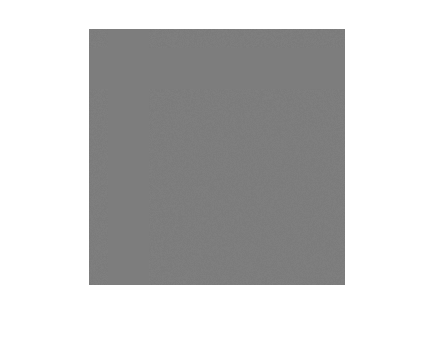

I3 = imread('red3.png');

figure, imshow(I3);

### Obrazek s roztazenym kontrastem

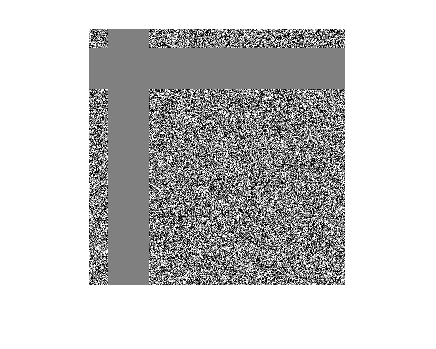

figure, imshow(I3,[]);

### Histogram

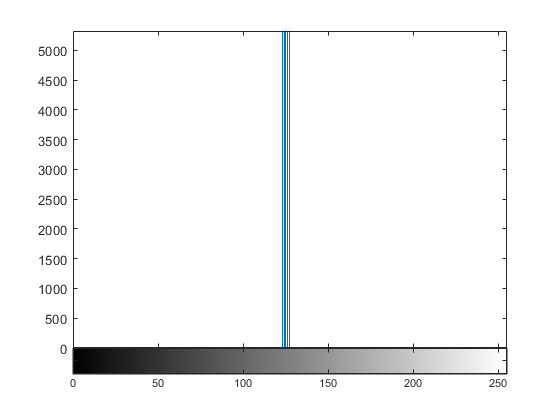

figure, imhist(I3,256);

## Entropie

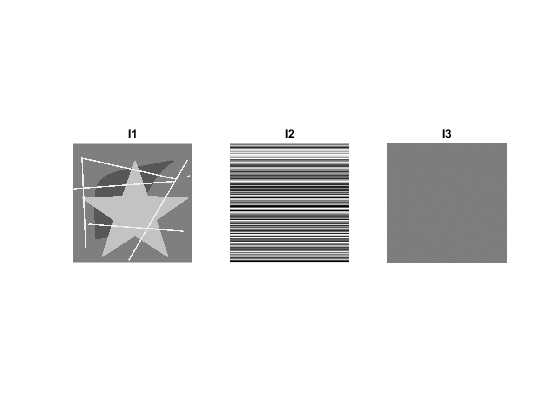

I1 = imread('red1.png');
figure,
subplot(1,3,1), imshow(I1);
title("I1");
I2 = imread('red2.png');
subplot(1,3,2),  imshow(I2);
title("I2");
I3 = imread('red3.png');
subplot(1,3,3),  imshow(I3);
title("I3");


J1 = entropy(I1);
J2 = entropy(I2);
J3 = entropy(I3);

display(J1);

J1 = 1.4884

display(J2);

J2 = 8

display(J3);

J3 = 2.1142

## Mean-squared error

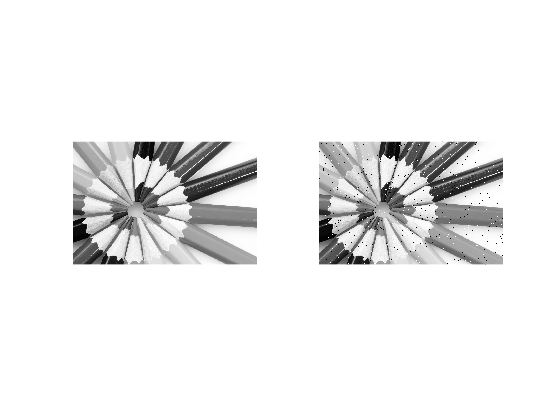

I = imread('pastelkygray.jpg');
I_noise = imnoise(I,'salt & pepper', 0.02);

figure,
subplot(1,2,1), imshow(I);
subplot(1,2,2), imshow(I_noise);


% immse = Mean-Squared Error.
mse = immse(I, I_noise);
display(mse);

mse = 456.7864


% root mean-squared error

rmse = sqrt(immse(I, I_noise));
display(rmse);

rmse = 21.3726

## UKOL 3

Spocitejte chybu pro obrazek red3.png (I3) a jeho upravu, kdy je nahrazen jednou hodnotou (Kazdy pixel ma hodnotu 125). 

## JPEG komprese

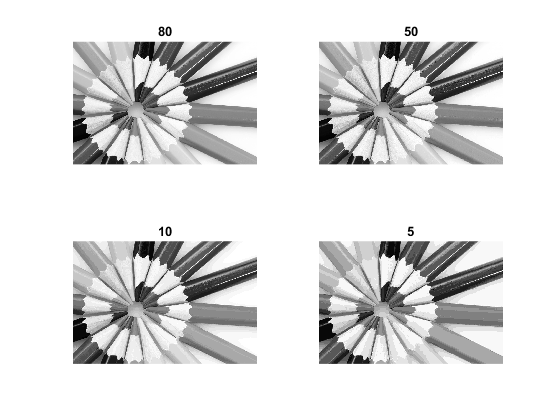

I = imread('pastelkygray.jpg');

imwrite(I,'p100.jpg','Quality', 100);
imwrite(I,'p80.jpg','Quality', 80);
imwrite(I,'p50.jpg','Quality', 50);
imwrite(I,'p10.jpg','Quality', 10);
imwrite(I,'p5.jpg','Quality', 5);

I1 = imread('p100.jpg');
I2 = imread('p80.jpg');
I3 = imread('p50.jpg');
I4 = imread('p10.jpg');
I5 = imread('p5.jpg');

figure,
subplot(2,2,1), imshow(I2);
title("80");
subplot(2,2,2), imshow(I3);
title("50");
subplot(2,2,3), imshow(I4);
title("10");
subplot(2,2,4), imshow(I5);
title("5");

imfinfo('p100.jpg')

ans = struct with fields:
           Filename: 'C:\Skola\vyuka2021-2022\ZS\PG\cvičení\cviceni8\p100.jpg'
        FileModDate: '14-Nov-2021 19:06:31'
           FileSize: 372656
             Format: 'jpg'
      FormatVersion: ''
              Width: 1400
             Height: 933
           BitDepth: 8
          ColorType: 'grayscale'
    FormatSignature: ''
    NumberOfSamples: 1
       CodingMethod: 'Huffman'
      CodingProcess: 'Sequential'
            Comment: {}


imfinfo('p5.jpg')

ans = struct with fields:
           Filename: 'C:\Skola\vyuka2021-2022\ZS\PG\cvičení\cviceni8\p5.jpg'
        FileModDate: '14-Nov-2021 19:06:31'
           FileSize: 22772
             Format: 'jpg'
      FormatVersion: ''
              Width: 1400
             Height: 933
           BitDepth: 8
          ColorType: 'grayscale'
    FormatSignature: ''
    NumberOfSamples: 1
       CodingMethod: 'Huffman'
      CodingProcess: 'Sequential'
            Comment: {}


## UKOL 4 (Vyberte si jedno z nasledujicich zadani)

- Naprogramujte funkci RLE, ktera bere jako vstup retezec a vraci kod vytvoreny kompresni metodou RLE.

- Naprogramujte funkci Huff, ktera bere jako vstup retezec a vraci pro vsechny znaky jejich kod vypocitany metodou Huffmanova kodovani.

- Naprogramujte nasledujici kroky jpeg komprese - prevod barev do YCbCr, dopredna kosinova transformace (pro matice 8x8), Vytvoreni vektoru z matice Zik-zak metodou.  